modulePath = 'C:/Users/Asus/Studia/Projekt IPS/dane - semestr 5/MATLAB_project/python_modules';
insert(py.sys.path, int32(0), modulePath);
load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

function pred_vector = model_chronos_expanding(y_train, y_test, step_length)
    modul = py.importlib.import_module('chronos_module_window');
    
    py.importlib.reload(modul);

    y_train_list = py.list(y_train(:)'); 
    y_test_list  = py.list(y_test(:)');
    
    result_list = modul.run_forecast_expanding(y_train_list, y_test_list, int32(step_length));
    
    pred_vector = result_list;
end

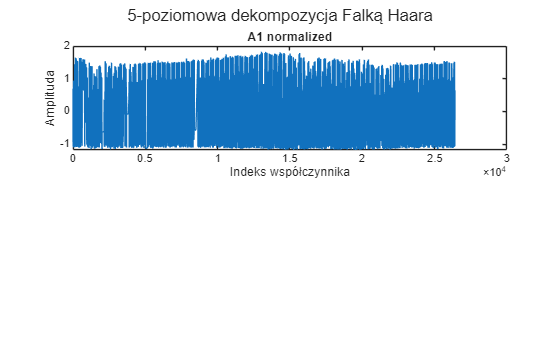

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);


% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[A1_norm, center_A1, scale_A1] = normalize(A1);

% 2. RYSOWANIE WYKRESÓW
figure;

subplot(2, 1, 1);
plot(A1_norm);
title('A1 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
A1_test_norm = (A1_test - center_A1) ./ scale_A1;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

dlugosc_testu_A1 = ceil(dlugosc_testu_oryginalna / 2);

% Przewidywania A1 - model hybrydowy
A1_pred_norm = model_chronos_expanding(A1_norm, A1_test_norm(1:dlugosc_testu_A1), 1)

CUDA dostepne: True
Wersja: 2.9.1+cu126
Ładowanie modelu Chronos-2 (Singleton)...
`torch_dtype` is deprecated! Use `dtype` instead!
`torch_dtype` is deprecated! Use `dtype` instead!
[Python Chronos] Start Expanding Window. Kroki: 1440, Step: 1
[Python Chronos] Krok 1/1440
[Python Chronos] Krok 2/1440
[Python Chronos] Krok 3/1440
[Python Chronos] Krok 4/1440
[Python Chronos] Krok 5/1440
[Python Chronos] Krok 6/1440
[Python Chronos] Krok 7/1440
[Python Chronos] Krok 8/1440
[Python Chronos] Krok 9/1440
[Python Chronos] Krok 10/1440
[Python Chronos] Krok 11/1440
[Python Chronos] Krok 12/1440
[Python Chronos] Krok 13/1440
[Python Chronos] Krok 14/1440
[Python Chronos] Krok 15/1440
[Python Chronos] Krok 16/1440
[Python Chronos] Krok 17/1440
[Python Chronos] Krok 18/1440
[Python Chronos] Krok 19/1440
[Python Chronos] Krok 20/1440
[Python Chronos] Krok 21/1440
[Python Chronos] Krok 22/1440
[Python Chronos] Krok 23/1440
[Python Chronos] Krok 24/1440
[Python Chronos] Krok 25/1440
[Python Chronos

A1_pred_norm =   Python list with values:

    [0.328125, -0.9609375, -0.97265625, -0.9921875, -0.9921875, -0.95703125, -0.9375, -0.94140625, -0.76171875, 0.8359375, -0.9609375, -0.97265625, -0.9375, -0.89453125, -0.921875, -0.85546875, -0.6953125, -0.376953125, -0.443359375, 1.1640625, -0.78125, -0.9296875, -0.9765625, -0.9921875, -0.99609375, -1.015625, -1.0078125, 0.427734375, 0.88671875, -0.271484375, -0.51171875, -1.0078125, -0.9921875, -1.015625, -1.015625, -1.0390625, -1.03125, -0.322265625, 0.8203125, -0.18359375, -0.80078125, -0.890625, -0.98828125, -0.99609375, -0.98828125, -1.015625, -1.0078125, -0.5625, 0.67578125, -0.1484375, -0.96875, -0.98828125, -0.98828125, -0.97265625, -0.9609375, -0.98828125, -0.96875, -0.392578125, 0.458984375, -0.054443359375, -0.8046875, 0.57421875, 1.3515625, 1.25, 1.328125, 1.421875, 1.453125, 1.46875, 1.4921875, 1.4375, 1.453125, 1.46875, 1.453125, 1.46875, 1.46875, 1.46875, 1.3

A1_pred_norm = A1_pred_norm.double

A1_pred_norm =     0.3281   -0.9609   -0.9727   -0.9922   -0.9922   -0.9570   -0.9375   -0.9414   -0.7617    0.8359   -0.9609   -0.9727   -0.9375   -0.8945   -0.9219   -0.8555   -0.6953   -0.3770   -0.4434    1.1641   -0.7812   -0.9297   -0.9766   -0.9922   -0.9961   -1.0156   -1.0078    0.4277    0.8867   -0.2715   -0.5117   -1.0078   -0.9922   -1.0156   -1.0156   -1.0391   -1.0312   -0.3223    0.8203   -0.1836   -0.8008   -0.8906   -0.9883   -0.9961   -0.9883   -1.0156   -1.0078   -0.5625    0.6758   -0.1484


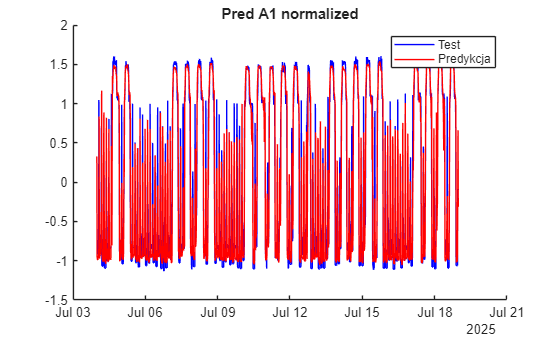

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_A1), A1_test_norm(1:dlugosc_testu_A1), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_A1), A1_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A1 normalized');
legend;

% DENORMALIZACJA
% Odwracamy proces: x = y * scale + center
A1_pred = (A1_pred_norm .* scale_A1) + center_A1;

D1_pred = zeros(length(A1_pred),1)';

final_prediction = idwt(A1_pred, D1_pred,'haar');      % podejście: A1 CHRONOS window

y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction)

mae_score = 0.0703

mape_score = mape(y_test, final_prediction)

mape_score = 34.8283

rmse_score = rmse(y_test, final_prediction)

rmse_score = 0.1257

r2_classic = R2_classic(y_test, final_prediction)

r2_classic = 0.8681

r2_alt = R2_alt(y_test, final_prediction)

r2_alt = 0.9389

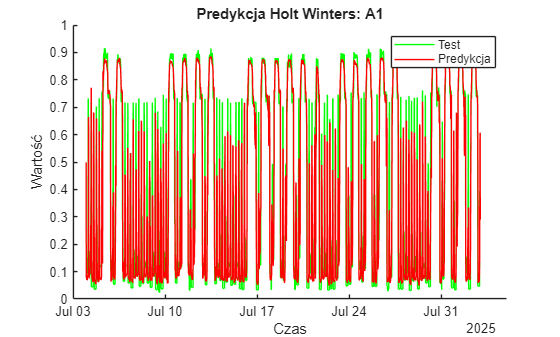


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(final_prediction)), ab_diff_test_norm(1:length(final_prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(final_prediction)), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters: A1")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   final_prediction', ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, 'pred_ab_A1_CHROMOS_month_1.xlsx');